# Lab 2 Problema 1: Aproximación de la siguiente integral sobre el círculo unitario centrado en el origen en el plan xy

### 
$$f{\left(x,y\right)}=∬_D {\;e}^{-x^2 -y^2 } dx\ dy$$


### Representación gráfica

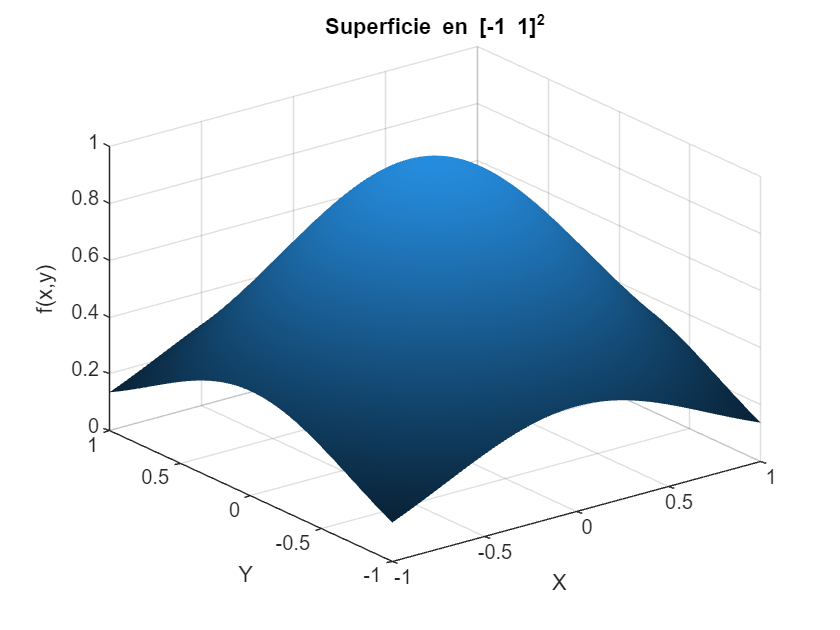

clear all; close all

% Definir el dominio de representación [-1 1]^2
a = -1; b = 1;    % a< x <b
c = -1; d = 1;    % c< y <d

resolution = 500; % Puntos de resolución para el mallado.

% Definir la superficie
f = @(x, y) exp(-x.^2 - y.^2);

% Se crea una malla de superficie
x = linspace(a, b, resolution); y = linspace(c, d, resolution);
[X, Y] = meshgrid(x, y); 

% Superficie evaluada en la malla.
F = f(X, Y); 

% Representación de la superficie en el dominio [-1 1]^2
figure(1)
surf(X, Y, F, 'EdgeColor', 'none'); % Malla sin bordes
colormap abyss; % Esquema de colores llamativo
xlabel('X'); ylabel('Y'); zlabel('f(x,y)');
title('Superficie en [-1 1]^2');

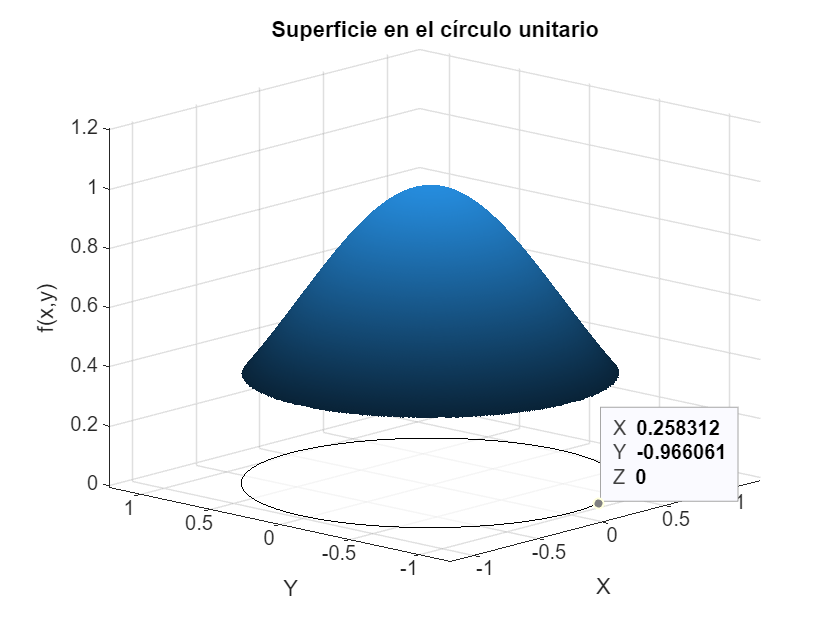

% Aplicar máscara para restringir la visualización al círculo
radio = 1;

mask = sqrt(X.^2 + Y.^2) > radio; % Puntos fuera del círculo
F(mask) = NaN; % Asignar NaN para que no se grafiquen

% Representación de la superficie en el dominio [-1 1]^2
figure(2), hold on, grid on;

surf(X, Y, F, 'EdgeColor', 'none'); % Malla sin bordes
colormap abyss; % Esquema de colores llamativo

theta = linspace(0, 2*pi, resolution); x_circle = cos(theta); y_circle = sin(theta);
fill3(x_circle, y_circle, zeros(size(x_circle)), 'w', 'EdgeColor', 'k', 'FaceAlpha', 0.7);

xlabel('X'); ylabel('Y'); zlabel('f(x,y)');
title('Superficie en el círculo unitario');
hold off;

xlim([-1.18 1.25])
ylim([-1.22 1.22])
zlim([-0.008 1.209])
view([-47.800 16.800])

### Integral con métodos numéricos

f_polar = @(r, theta) exp(-r.^2 .* cos(theta).^2 -r.^2 .* sin(theta).^2);

f_polar = exp(-r.^2 .* (cos(theta).^2 + sin(theta).^2));

f_polar = exp(-r.^2);

% Calcular el valor exacto de la integral
f_polar = @(r, theta) exp(-r.^2); % Definir la función en coordenadas polares

vol_real = integral2(@(r, theta) f_polar(r, theta) .* r, ...
                           0, 1, ...        % r va de 0 a 1 (círculo unitario)
                           0, 2*pi);        % theta va de 0 a 2π (círculo completo)
% Mostrar resultado
fprintf('El valor real de la integral es: %.6f\n', vol_real);

El valor real de la integral es: 1.985865


### Integral con aproximación de Monte Carlo

% Iniciar el experimento de Monte Carlo
n = 5000; % numero de intentos

function [vol_esti, idx, x_rnums, y_rnums, z_rnums] = monte_carlo(n, f, a, b, c, d)
    % Generamos una nube de n puntos en el polígono [a, b] x [c, d] x h
    random_nums = rand(n, 3); % n x 3 números aleatorios uniformes entre 0 y 1 
    
    % Los puntos siguen una distribución uniforme en los intervalos
    % [a, b], [c, d] y [0, h], donde h es una cota superior de f
    x_rnums = a + random_nums(:,1)*(b - a);         
    y_rnums = c + random_nums(:,2)*(d - c); 
    h = max(f(x_rnums, y_rnums)); % Altura del polígono de trabajo
    z_rnums = random_nums(:, 3)*h;
    
    % Cálculo del volumen del polígono de trabajo
    vol_pol = (b - a)*(d - c)*h;

    % Localizar los puntos que se encuentran debajo de la superficie f y dentro
    % del círculo unidad
    g = @(x_rnums, y_rnums) sqrt(x_rnums.^2 + y_rnums.^2); % Función que define un círculo
    idx = (z_rnums <= f(x_rnums, y_rnums) & g(x_rnums, y_rnums) < 1); % radio unitario
    
    % Aproximación del volumen buscado
    nc = sum(idx); % Contar el número de valores que están dentro del volumen buyscado
    vol_esti = vol_pol*nc/n;
end

[vol_esti, idx, x_rnums, y_rnums, z_rnums] = monte_carlo(n, f, a, b, c, d);
fprintf('El valor aproximado de la integral es: %.6f\n', vol_esti);

El valor aproximado de la integral es: 1.976284


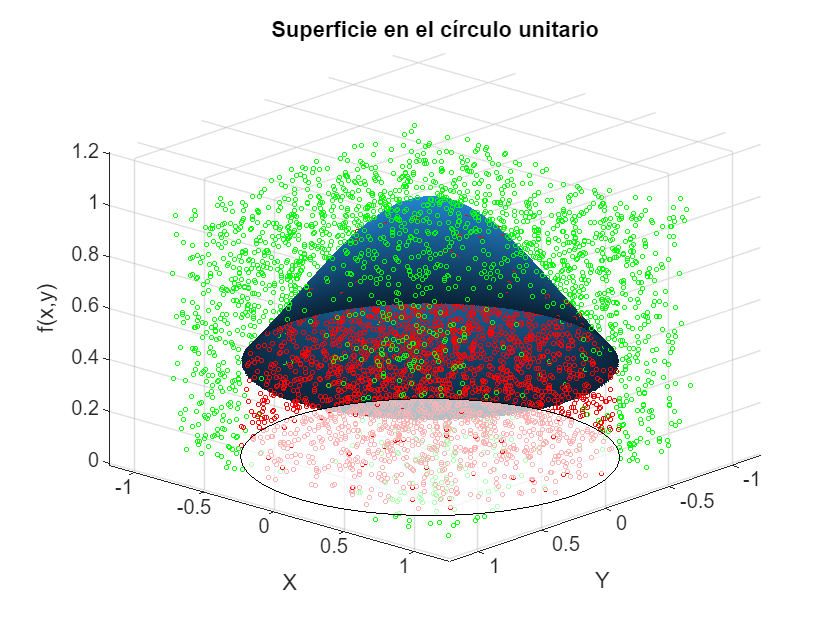

% Representación de la aproximación de Monte Carlo
if exist('f3', 'var') && ishandle(f3)
    close(f3);
end

f3 = figure(3);
hold on, grid on;

surf(X, Y, F, 'EdgeColor', 'none'); % Malla sin bordes
colormap abyss; % Esquema de colores llamativo

theta = linspace(0, 2*pi, resolution); x_circle = cos(theta); y_circle = sin(theta);
fill3(x_circle, y_circle, zeros(size(x_circle)), 'w', 'EdgeColor', 'k', 'FaceAlpha', 0.7);

plot3(x_rnums(idx,1),y_rnums(idx,1),z_rnums(idx,1),'ro','MarkerSize',2) % Puntos que satisfacen el criterio
plot3(x_rnums(~idx,1),y_rnums(~idx,1),z_rnums(~idx,1),'go','MarkerSize',2) % Puntos que no satisfacen el criterio

xlabel('X'); ylabel('Y'); zlabel('f(x,y)');
title('Superficie en el círculo unitario');
hold off;

xlim([-1.18 1.25])
ylim([-1.22 1.22])
zlim([-0.008 1.209])
view([-42.400 -24.400])

### Comparación de resultados

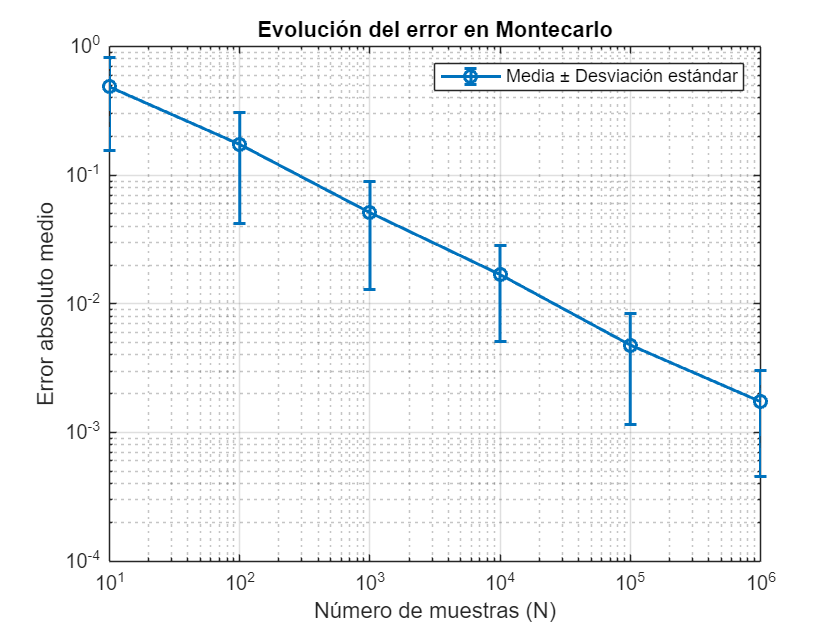


%error = abs(vol_real - vol_esti);

% Parámetros
num_experimentos = 100;  % Número de veces que repetimos Montecarlo por cada N
num_muestras = round(logspace(1, 6, 6)); % Diferentes tamaños de muestra (de 10^2 a 10^5)
%valor_exacto = pi; % Suponiendo que queremos estimar π como ejemplo

% Inicializar matriz de errores
errores = zeros(length(num_muestras), num_experimentos);

% Loop sobre el número de muestras
for i = 1:length(num_muestras)
    N = num_muestras(i);
    for j = 1:num_experimentos
        % Método de Montecarlo: Aproximación de π
        [vol_esti, idx, x_rnums, y_rnums, z_rnums] = monte_carlo(N, f, a, b, c, d);

        % Calcular error absoluto
        errores(i, j) = abs(vol_esti - vol_real);
    end
end

% Calcular el error medio y la desviación estándar
error_medio = mean(errores, 2);
error_std = std(errores, 0, 2);

% Graficar evolución del error
figure;
errorbar(num_muestras, error_medio, error_std, 'o-', 'LineWidth', 1.5);
set(gca, 'XScale', 'log', 'YScale', 'log'); % Escala logarítmica
grid on;
xlabel('Número de muestras (N)');
ylabel('Error absoluto medio');
title('Evolución del error en Montecarlo');
legend('Media ± Desviación estándar');